GPU Check

gpuDeviceTable

ans = 1×5 table
    Index              Name               ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3070"          "8.6"               true              true      


Set GPU

gpuDevice(1)

ans =   CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589279232 (8.59 GB)
      AvailableMemory: 7443034112 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

Parameters

name = "ResNet50"

name = "ResNet50"

batch_size = 20

batch_size = 20

epochs = 1

epochs = 1

learn_rate = 0.001;

model_directory = strcat("RCNN/", name, "/MathLab_Data")

model_directory = "RCNN/ResNet50/MathLab_Data"

mkdir(model_directory)
mkdir(model_directory + "/training")
%mkdir(model_directory + "/validation")
mkdir(model_directory + "/final_test_results")

Loading train ground truths

load("RCNN/GTTrain.mat")

Train model

*******************************************************************
Training an R-CNN Object Detector for the following object classes:

* Edible
* Poisonous

--> Extracting region proposals from 1800 training images...done.



--> Training a neural network to classify objects in training data...

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       35.00% |       1.1396 |          0.0010 |
|       1 |          50 |       00:00:16 |       90.00% |       0.3259 |          0.0010 |
|       1 |         100 |       00:00:29 |       85.00% |       0.3409 |          0.0010 |
|       1 |         150 |       00:00:42 |       80.00% |       0.3048 |          0.0010 |
|       1 |         200 |       00:00:56 |       90.00% |       0.2711 |          0.0010 |
|       1 |         250 |       00:01:09 |      100.00% |       0.0671 

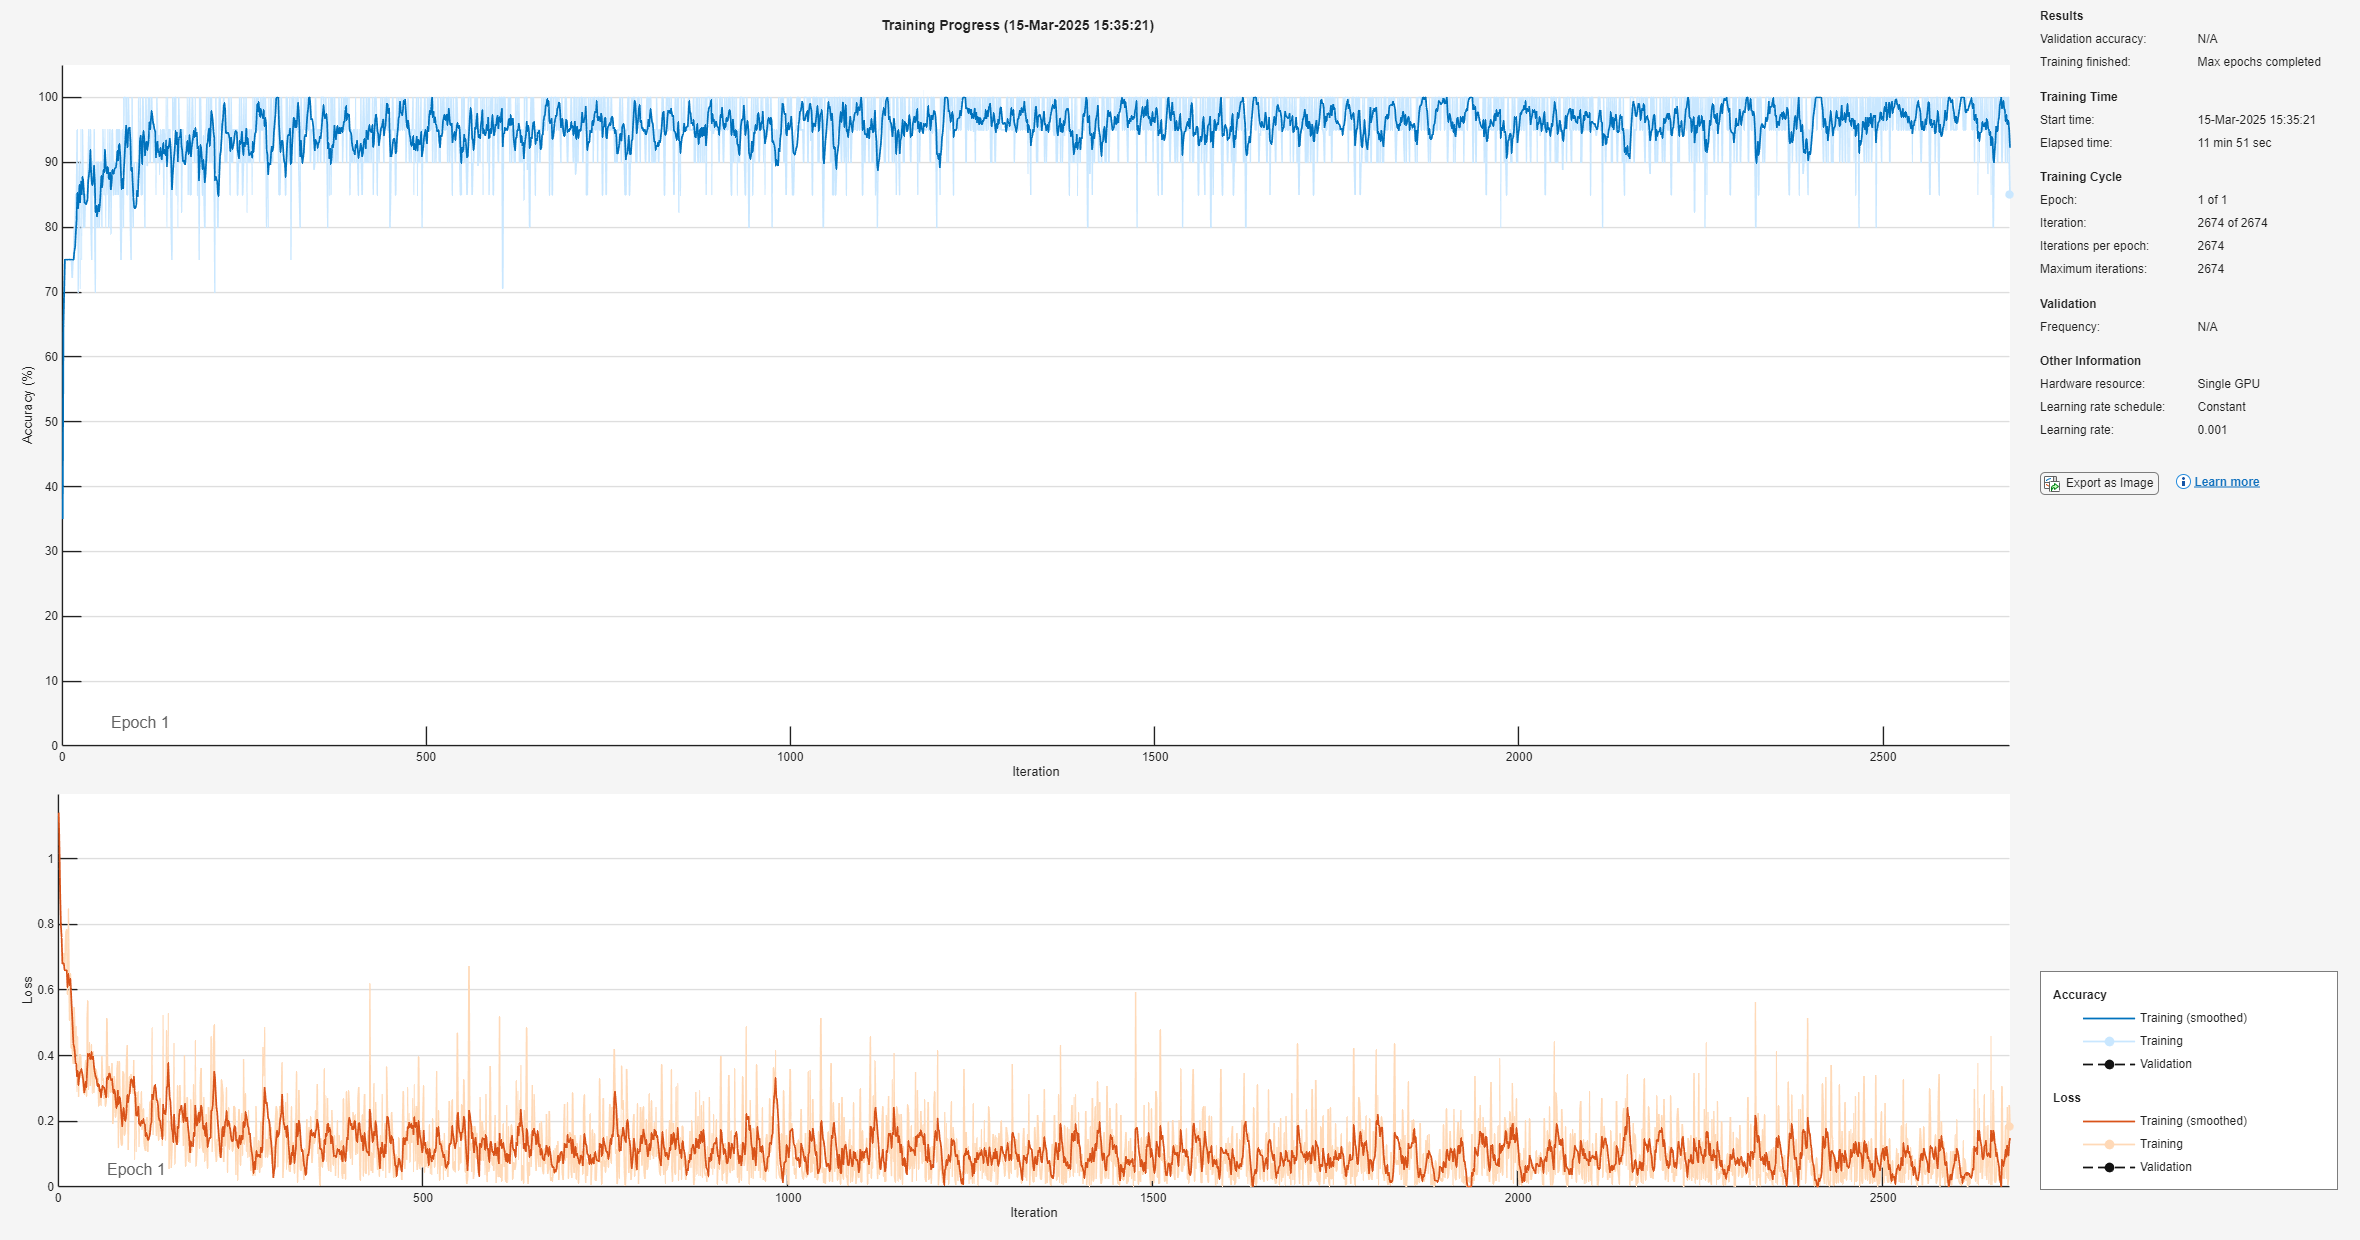


Network training complete.

--> Training bounding box regression models for each object class...100.00%...done.

Detector training complete.
*******************************************************************



options = trainingOptions('sgdm', ...
  'MiniBatchSize', batch_size, ...
  'InitialLearnRate', learn_rate, ...
  'MaxEpochs', epochs, ...
  'ExecutionEnvironment', 'gpu', ...
  'PreprocessingEnvironment','parallel', ...
  'Plots', 'training-progress');

[net, info] = trainRCNNObjectDetector(GTTrain, "resnet50", options, "NegativeOverlapRange", [0 0.5]);

Time : 

AlexNet : 2 min 50s

ResNet50 : 11 min 51s

GoogleNet :  5 min 40s

ArticleNet :

save("RCNN/" + name + "/" + name + "_model.mat", "net")

Exporting training data

iterations = size(info.TrainingAccuracy);
iterations = iterations(2);

train = table(reshape(info.TrainingAccuracy, [iterations, 1]));
writetable(train, model_directory + "/training/" + name + "_acc.csv");

val = table(reshape(info.TrainingLoss, [iterations, 1]));
writetable(val, model_directory + "/training/" + name + "_loss.csv");

Making examples

exmp_img = imread("Mushroom dataset\r-cnn\Poisonous\img0238.jpg");

[bbox, score, label] = detect(net, exmp_img, ExecutionEnvironment="gpu")

bbox =    138    71   114   178
    47    88   163   129


score = 2×1 single column vector
    0.9291
    1.0000


label = 2×1 categorical array
     Poisonous 
     Poisonous 


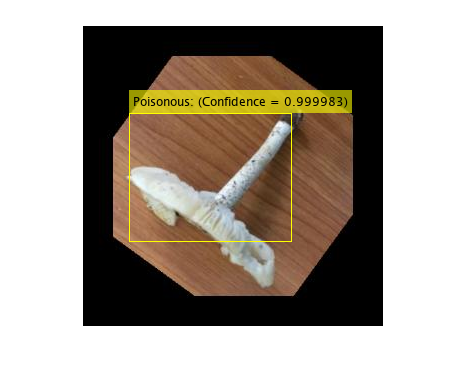

[score, idx] = max(score);

bbox = bbox(idx, :);
annotation = sprintf('%s: (Confidence = %f)', label(idx), score);

detectedImg = insertObjectAnnotation(exmp_img, 'rectangle', bbox, annotation);

figure
imshow(detectedImg)

Export example

imwrite(detectedImg, "RCNN/Example3.png")

Load test set

load("RCNN/RCNNTest.mat")

Compute predictions

blank_count = 0;

test_set_size = size(RCNNTest.img_col);
test_set_size = test_set_size(1);

y_predicted = categorical(200, 1);
y_test = RCNNTest.lable_col;

for i = 1:test_set_size
    
    test_image = imread(string(RCNNTest.img_col(i)));
    [~, score, label] = detect(net, test_image, MiniBatchSize=20, ExecutionEnvironment="gpu");
    [score, idx] = max(score);

    if isempty(label) == false
        y_predicted(i, :) = label(idx);
    else
        blank_count = blank_count + 1;
        disp("Model blanked " + string(blank_count));
        disp(string(RCNNTest.img_col(i)))

        rnd = rand;
        if rnd > 0.5
            y_predicted(i, :) = categorical("Edible");
        else
            y_predicted(i, :) = categorical("Poisonous");
        end
    end
end

Model blanked 1


C:\Users\Willoghby\Desktop\NN\NeuronoveSiete-Zadanie1\RCNN\SegmentedDataset\Edible\1024-1280\img04259.jpg


Model blanked 2


C:\Users\Willoghby\Desktop\NN\NeuronoveSiete-Zadanie1\RCNN\SegmentedDataset\Edible\1280-1473\img04417.jpg


Model blanked 3


C:\Users\Willoghby\Desktop\NN\NeuronoveSiete-Zadanie1\RCNN\SegmentedDataset\Edible\1280-1473\img04430.jpg


Model blanked 4


C:\Users\Willoghby\Desktop\NN\NeuronoveSiete-Zadanie1\RCNN\SegmentedDataset\Edible\512-768\img1193.jpg


Model blanked 5


C:\Users\Willoghby\Desktop\NN\NeuronoveSiete-Zadanie1\RCNN\SegmentedDataset\Edible\1024-1280\img3129.jpg


Model blanked 6


C:\Users\Willoghby\Desktop\NN\NeuronoveSiete-Zadanie1\RCNN\SegmentedDataset\Poisonous\1-256\img0214.jpg


Model blanked 7


C:\Users\Willoghby\Desktop\NN\NeuronoveSiete-Zadanie1\RCNN\SegmentedDataset\Edible\1024-1280\img3117.jpg


Model blanked 8


C:\Users\Willoghby\Desktop\NN\NeuronoveSiete-Zadanie1\RCNN\SegmentedDataset\Edible\256-512\img267.jpg


Model blanked 9


C:\Users\Willoghby\Desktop\NN\NeuronoveSiete-Zadanie1\RCNN\SegmentedDataset\Edible\512-768\img1139.jpg


Model blanked 10


C:\Users\Willoghby\Desktop\NN\NeuronoveSiete-Zadanie1\RCNN\SegmentedDataset\Edible\256-512\img331.jpg


Export predictions

pred = array2table(y_predicted);
test = array2table(y_test);

disp("Exporting final results...")

Exporting final results...



writetable(pred, model_directory + "/final_test_results/y_predicted.csv");
writetable(test, model_directory + "/final_test_results/y_test.csv");

disp("Done")

Done
